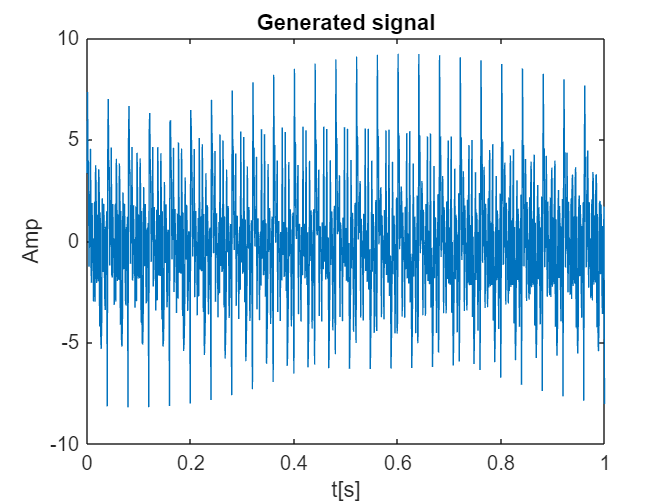

clear all

% Generating multisine
Nfreq = 19;
dfreq = 25;
maxFreq = 500;
minFreq = 25;
fi = minFreq:((maxFreq-2*minFreq)/(Nfreq-1)):maxFreq;
fi = fi(1:Nfreq);
phase_i = rand(1,Nfreq)*pi-pi/2;

dt = 1/1024;
t = [0:dt:25/fi(1)-dt];

y_temp = 0;
for i = 1:Nfreq
    y_temp = y_temp + sin(2*pi*fi(i)*t+phase_i(i));
end

plot(t,y_temp);
title('Generated signal')
xlabel('t[s]');
ylabel('Amp')

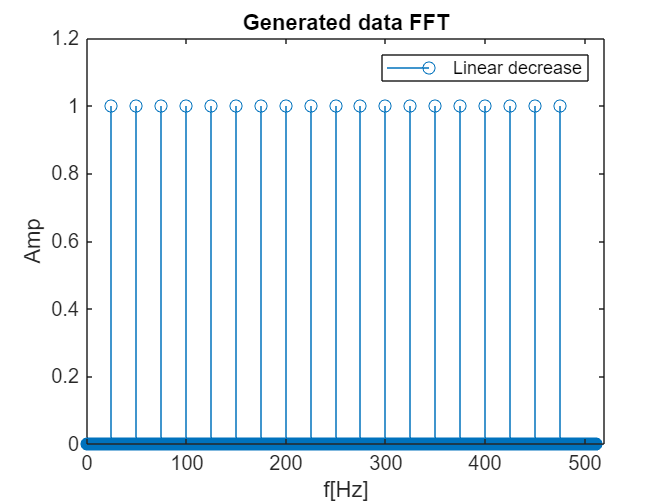



% Spectre of generated signal
Y_c = fft(y_temp);
Y = abs(fft(y_temp))/length(t);
N = length(t);
df = (1/(N*dt));
f = [0:df:(1/dt)-df];
f_egy = f(1:end/2);
Y(2:end) = 2*Y(2:end);
Y_egy = Y(1:end/2);
stem(f_egy,Y_egy)
xlim([0,520])
legend('Linear decrease')
title('Generated data FFT')
xlabel('f[Hz]')
ylabel('Amp')

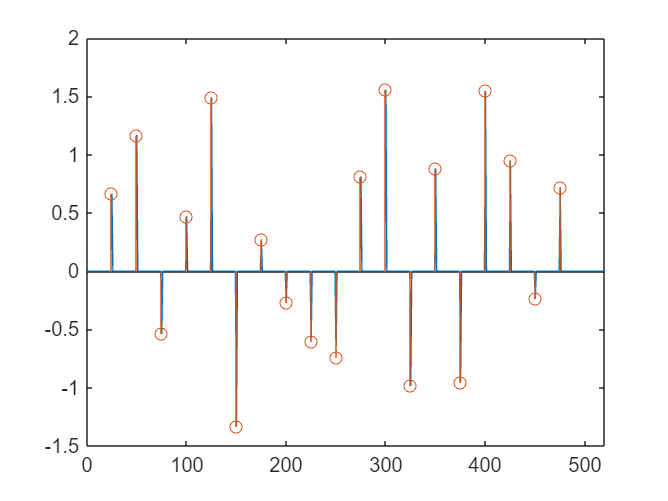


% Clearing numerical noise from spectre (dividint with small real part causes error)

Y_c2=Y_c;%store the FFT results in another array
%detect noise (very small numbers (eps)) and ignore them
threshold = max(abs(Y_c))/10000; %tolerance threshold
Y_c2(abs(Y_c)<threshold) = 0; %maskout values that are below the threshold

% Setting the reference

phaseSpect = angle(Y_c2);
phaseSpect(f(fi)+2) = phaseSpect(f(fi)+2)+pi/2;

plot(f,phaseSpect)
hold on
stem(fi,phase_i)
xlim([0,520])
hold off

% Writing data to file

N = 16;
y_std = y_temp-min(y_temp) % XD OK

y_std =     4.9215   10.5074    7.8518   10.9098    7.3956   10.6141   10.5996    2.7283   11.7174    6.7198    4.8550    1.5119    8.0279    9.0726    7.7696   11.6201   10.3271    8.4816    7.1042    4.5807   12.8218   11.4818         0    8.2934    7.9226    8.7131   11.3789    5.4195    2.5247    5.2418    5.3480    6.3486    5.0697    8.7414    9.2257    5.6529    2.9811    4.6819    4.7455    6.6773   11.0220    4.9205   10.6515    7.7353   11.0641    7.1431   11.0268   10.0809    2.9522   11.8115


y = y_std/max(y_std)

y =     0.3149    0.6724    0.5025    0.6981    0.4733    0.6792    0.6783    0.1746    0.7498    0.4300    0.3107    0.0968    0.5137    0.5806    0.4972    0.7436    0.6609    0.5428    0.4546    0.2931    0.8205    0.7347         0    0.5307    0.5070    0.5576    0.7282    0.3468    0.1616    0.3354    0.3422    0.4063    0.3244    0.5594    0.5904    0.3617    0.1908    0.2996    0.3037    0.4273    0.7053    0.3149    0.6816    0.4950    0.7080    0.4571    0.7056    0.6451    0.1889    0.7558


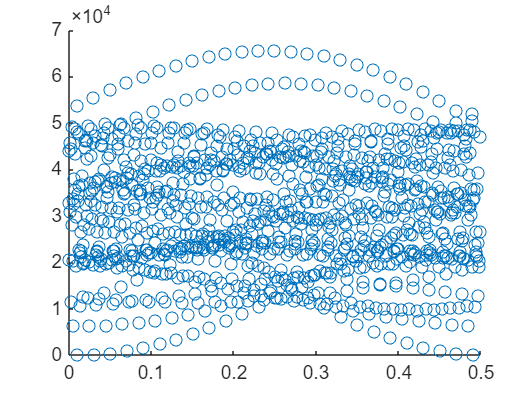

%plot(y)
y_hex = floor(y*(2^N-1));
scatter(t,y_hex)


hex_sine = dec2hex(y_hex);
MSB = bitshift(y_hex,-8) ;
msb_sine = "0x"+string(dec2hex(MSB));
lsb_sine = "0x"+string(dec2hex(y_hex-MSB*2^8));

mcu_sin = [msb_sine,lsb_sine];
mcu_sin_reshaped = reshape(mcu_sin',1,[]);

%writing to file for MCU
folder = "C:\Users\Peter\STM32CubeIDE\workspace_1.12.0\RedPill_DAC_SPI_MultiSin_FFT\Core\Src\";
fid = fopen(folder+"dacMultiSine.txt",'wt');
fprintf(fid,'%s,', mcu_sin_reshaped{1:end-1});
fprintf(fid,'%s', mcu_sin_reshaped{end});
fclose(fid);

% Processing data

% Spectre of measured signal: Input signal, Rn signal, Impedance signal,
% Uz/Un amplitude spectre

% There are data in the A,J,S columns in the dacWhiteFFT.xlsl - 3 separate
% measurements.
clear all

fileWhite = 'dacWhiteFFT.xlsx';
fileN = 'dacNfreqFFT.xlsx';
range1 = 'A1:A450';
range2 = 'J1:J450';
range3 = 'S1:S450';


T = readtable(fileWhite,'Sheet','Absolute','Range',range1,'ReadVariableNames', false);
T1 = T{:,1};
T1_double = [str2double(split(T1,','))]

T1_double =    1.592040000000000  18.253660000000000   1.591800000000000   0.011200000000000
   0.019040000000000   0.614580000000000   0.018950000000000   0.063330000000000
   0.021640000000000   1.183340000000000   0.021650000000000   0.106780000000000
   0.025290000000000   1.738060000000000   0.025230000000000   0.134560000000000
   0.028910000000000   0.774230000000000   0.029010000000000   0.052130000000000
   0.032440000000000   1.257540000000000   0.032450000000000   0.075690000000000
   0.035470000000000   2.440980000000000   0.035370000000000   0.134810000000000
   0.037670000000000   2.049560000000000   0.037750000000000   0.106030000000000
   0.038950000000000   0.863430000000000   0.039120000000000   0.043110000000000
   0.039630000000000   1.501970000000000   0.039620000000000   0.074050000000000


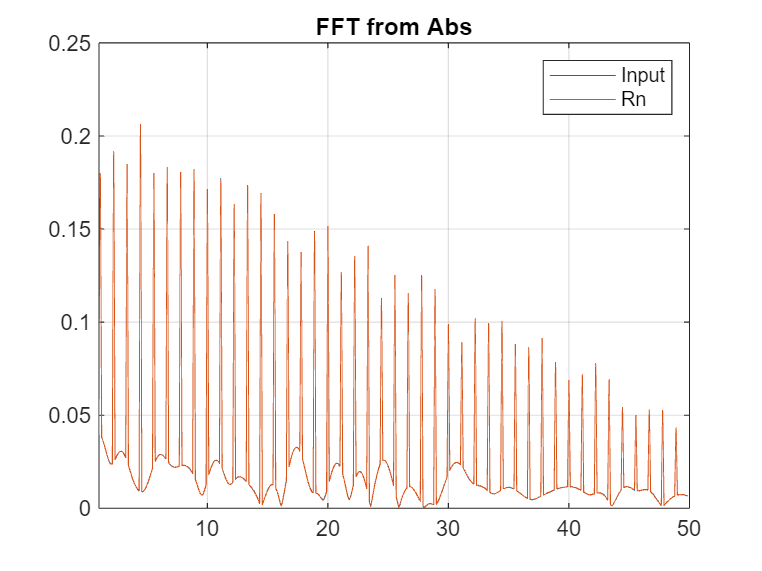


Y_in_a = T1_double(:,1);
Y_imp_a = T1_double(:,2);
Y_ref_a = T1_double(:,3);

N = 2*length(Y_in_a);
fs = 100;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

% Measurement without impedance: ADC_IN8 and ADC_IN9 are the same, hence
% their diff is small, it's spectre is noise.

% Plotting FFTs
figure()
plot(f_egy,Y_in_a);
hold on
% plot(f_egy,Y_imp); % no need to plot
plot(f_egy,Y_ref_a);
hold off
xlim([1,50]);
title('FFT from Abs')
legend('Input','Rn')
grid on


% Peak freqs from Z/N spectre: 0.01658, 0.01405

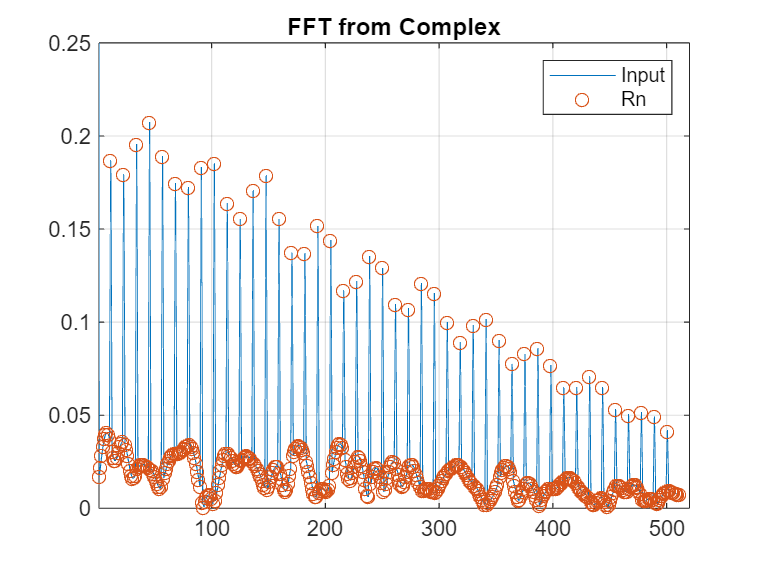

% Complex spectres
% complexSpectres.csv - In sign (real,imag), Imp (real, imag), Ref resistor
% sig (real, imag), Uz/Un (real,imag)
clear all

fileWhite = 'dacWhiteFFT.xlsx';
fileN = 'dacNfreqFFT.xlsx';
range1 = 'A1:A450';
range2 = 'J1:J450';
range3 = 'S1:S450';

FFT_BUFFER_SIZE = 1024;
T = readtable(fileWhite,'Sheet','Complex','Range',range1,'ReadVariableNames', false);
T1 = T{:,1};
T1_double = [str2double(split(T1,','))];

Yin_c = T1_double(:,1)+1i*T1_double(:,2);
Yimp_c = T1_double(:,3)+1i*T1_double(:,4);
Yref_c = T1_double(:,5)+1i*T1_double(:,6);
Y_in = abs(Yin_c)*2/FFT_BUFFER_SIZE; % they're maybe single sided - ARM FFT
Y_imp = abs(Yimp_c)*2/FFT_BUFFER_SIZE;
Y_ref = abs(Yref_c)*2/FFT_BUFFER_SIZE;
Y_in(1) = Y_in(1)/2;
Y_imp(1) = Y_imp(1)/2;
Y_ref(1) = Y_ref(1)/2;

N = 2*length(Yin_c);
fs = 1024;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

figure()
plot(f_egy,Y_in);
hold on
% plot(f_egy,Y_imp); % no need to plot
scatter(f_egy,Y_ref);
title('FFT from Complex')
legend('Input','Rn')
grid on
xlim([1,520])

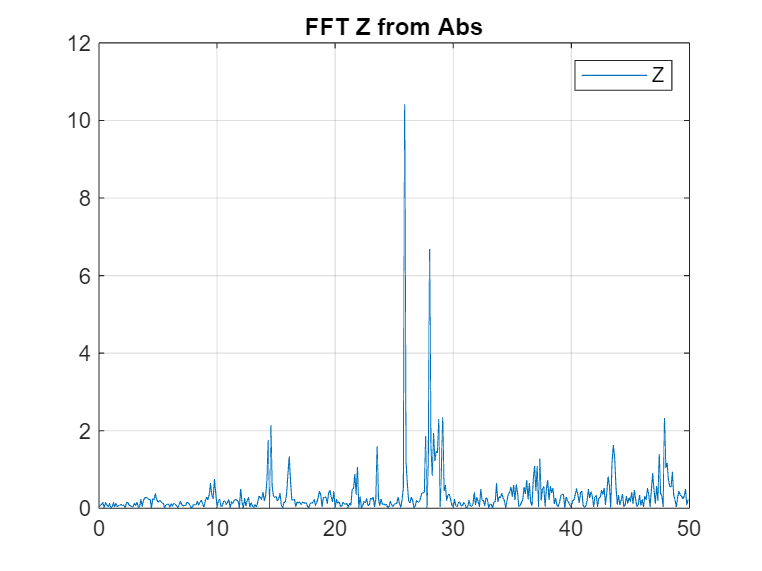

% Measured impedance spectre

% Ez most hülyeség, mert az impedancia jele is zaj

% Measure abs
clear all

fileWhite = 'dacWhiteFFT.xlsx';
fileN = 'dacNfreqFFT.xlsx';
range1 = 'A1:A450';
range2 = 'J1:J450';
range3 = 'S1:S450';

T = readtable(fileWhite,'Sheet','Absolute','Range',range2,'ReadVariableNames', false);
T1 = T{:,1};
T1a_double = [str2double(split(T1,','))];

Z_a = T1a_double(:,4);

N = 2*length(Z_a);
fs = 100;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

% Plotting FFTs
figure()
plot(f_egy,Z_a);
xlim([0,50]);
title('FFT Z from Abs')
legend('Z')
grid on

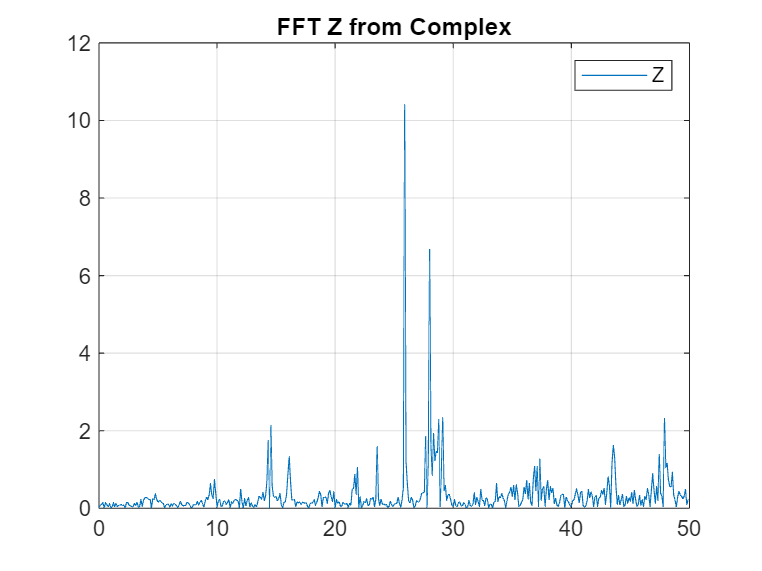


% Measured complex
FFT_BUFFER_SIZE = 1024;
T = readtable(fileWhite,'Sheet','Complex','Range',range2,'ReadVariableNames', false);
T1 = T{:,1};
T1c_double = [str2double(split(T1,','))];
Z_c = T1c_double(:,7)+1i*T1c_double(:,8);
Z = abs(Z_c)*2/FFT_BUFFER_SIZE;
Z(1) = Z(1)/2;

N = 2*length(Z_c);
fs = 100;
df = fs/N;
f = [0:df:(N-1)*df];
f_egy = f(1:end/2);

figure()
plot(f_egy,Z);
title('FFT Z from Complex')
legend('Z')
grid on

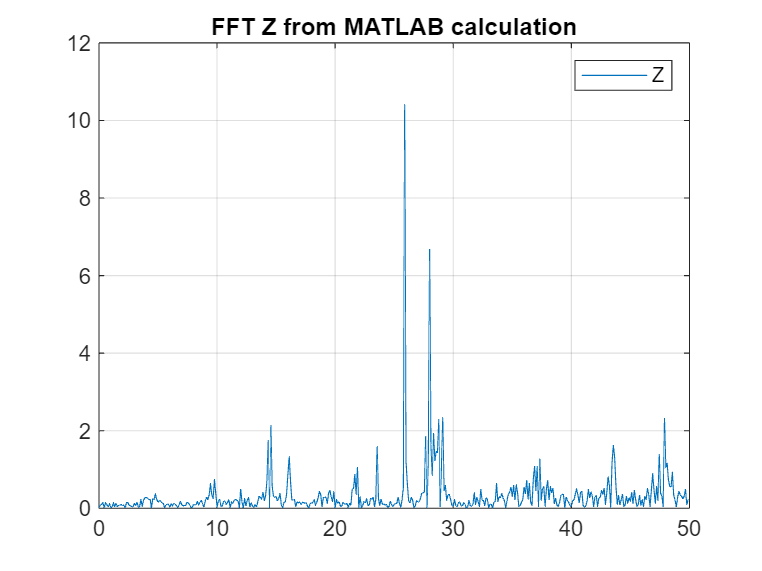


% Calculated in MATLAB
Yimp_c = T1c_double(:,3)+1i*T1c_double(:,4);
Yref_c = T1c_double(:,5)+1i*T1c_double(:,6);
Z_c_calc = Yimp_c./Yref_c;
Z_calc = abs(Z_c_calc)*2/FFT_BUFFER_SIZE;
Z_calc(1) = Z_calc(1)/2;

figure()
plot(f_egy,Z_calc);
title('FFT Z from MATLAB calculation')
legend('Z')
grid on


% MATLAB complex division result matches the calculated on the MCU, so the
% algorithm is okay